# Métodos Numéricos y Programación

*F. Pena*

## Tema 1. Introducción, variables y funciones

### Partes de Matlab

#### Base

Parte común: calculo, gráficas, ...

a = 5

a = 5

sin(a)

ans = -0.9589

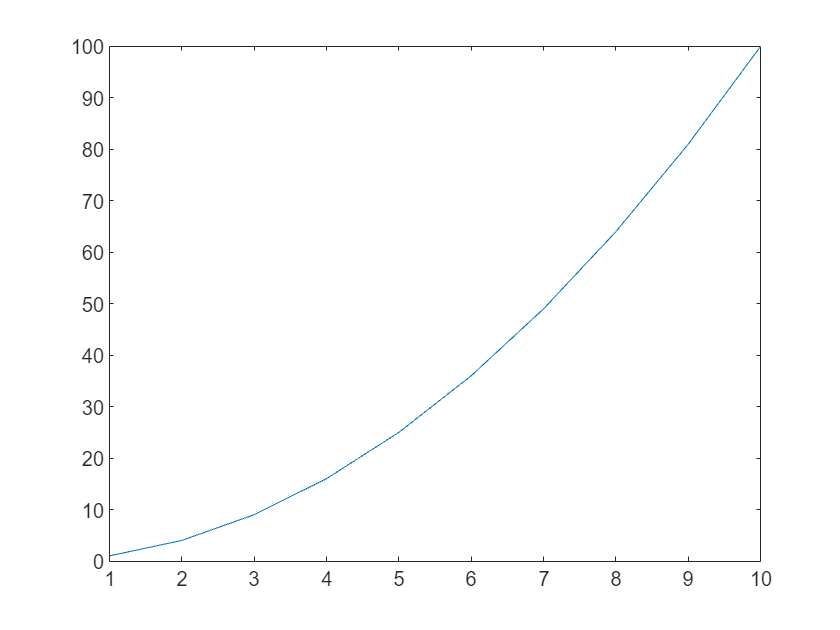

plot(1:10, (1:10).^2)

#### Toolboxes

- Se instalan (pagan) por separado.

- Herramienta **symbolic**:

syms x
diff(sin(x))

$$ans = \cos\left(x\right)$$

- Herramienta **pdetool**:

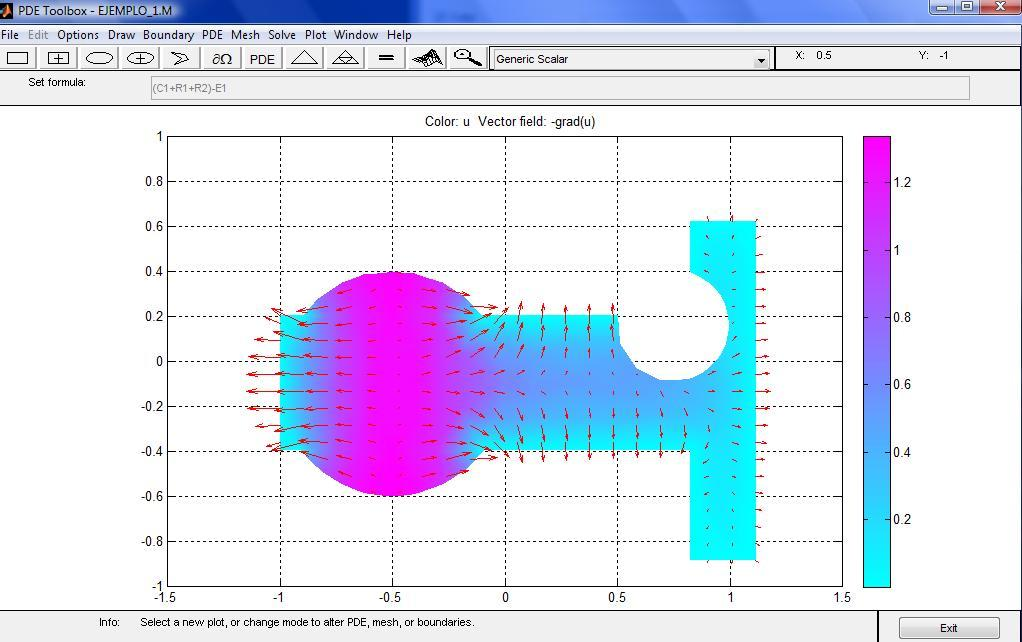

- [`Simulink`](https://es.mathworks.com/products/simulink.html) (diseño basado en modelos), similar a [`Modelica`](https://modelica.org/).

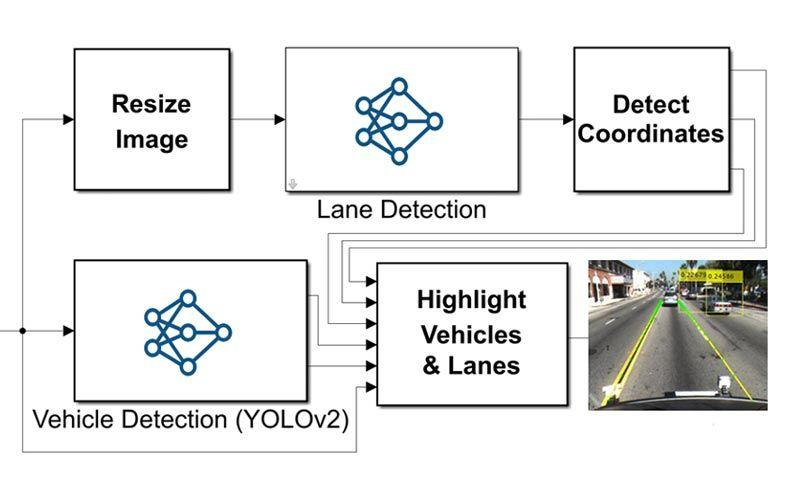

#### Ventana de comandos 

- Ejecución "uno a uno".

- Recuperación de comandos. 

#### Editor

- Archivos **.m** con comandos (*scripts*) o con funciones (*function*).

- Ejecución:  `archivo_sin_extension`

#### Editor Live

- Archivos **.mlx**

- Texto enriquecido mezclado con celdas de cálculo. 

- Permite incluir índices, listas, formulas matemáticas como $\frac{\sqrt{x}}{2}$, imágenes, etc.

- Secciones y celdas de comandos.

- Son* scripts* con funciones locales.

#### Ayuda

- Documentación en ventana de comandos y enlace a ventana de ayuda,  `>> help ``comando`

- [Documentación web](https://es.mathworks.com/help/matlab/), al contrario que el anterior, no tiene que ser para la versión instalada.

### Variables

Se crean en el espacio de trabajo de Matlab, o *workspace.*

#### Tipos básicos

- Enteros y reales: `double`

clear % borra las variables creadas previamente
a = 1/3

a = 0.3333

b = 1; % se calcula pero no se muestra en pantalla
2+2    % por defecto, se asigna a la variable ans

ans = 4

whos

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              
  ans       1x1                 8  double              
  b         1x1                 8  double              



format long % formato double del estandar IEEE-754
a

a =    0.333333333333333


format short
a

a = 0.3333

eps % argmin({x>0 | 1+x ~= 1}

ans = 2.2204e-16

- Lógico: `0`, falso, `~= 0`, cierto. También `false`, `true`.

1>2, 1<2

ans = logical
   0


ans = logical
   1


whos % ahora ans es logical

  Name      Size            Bytes  Class      Attributes

  a         1x1                 8  double               
  ans       1x1                 1  logical              
  b         1x1                 8  double               



- Cadenas: entre comillas simples o dobles.

disp(['El valor de pi/2 es ' num2str(pi/2)])

El valor de pi/2 es 1.5708


#### Tipos compuestos

- **Vectores**

[4,5] == [4 5] 

ans = 1×2 logical array
   1   1


% no siempre los espacios en las fórmulas son irrelevantes
[a +5], [a+5] % ¡OJO!, [a +5] no es lo mismo que [a+5]

ans =     0.3333    5.0000


ans = 5.3333

v = 2:2:11 % creación automática de vectores

v =      2     4     6     8    10


x = linspace(1, 100, 10)

x =      1    12    23    34    45    56    67    78    89   100


x(v)

ans =     12    34    56    78   100


x(5:end-1)

ans =     45    56    67    78    89


dot(v, x(5:end-1))

ans = 2230

cross(v(1:3), x(7:end-1)) % el producto vectorial sólo está definido para vectores de R^3

ans =   -112   224  -112


sum(v)

ans = 30

norm(v,1) % norma 1, suma del valor absoluto de las componentes

ans = 30

setdiff(v, [2 3])

ans =      4     6     8    10


sort([-1 2 0])

ans =     -1     0     2


unique([1 2 2 3])

ans =      1     2     3


- **Matrices**

A = [1 2 3 4; 5 6 7 0]

A =      1     2     3     4
     5     6     7     0


size(A)

ans =      2     4


A(1,:) 

ans =      1     2     3     4


A(1:end-1, 2:2:end)

ans =      2     4


[A; 9 0 0 0] 

ans =      1     2     3     4
     5     6     7     0
     9     0     0     0


[A [10; 100]]

ans =      1     2     3     4    10
     5     6     7     0   100


triu(A), tril(A)

ans =      1     2     3     4
     0     6     7     0


ans =      1     0     0     0
     5     6     0     0


diag([ 1 2; 3 4])

ans =      1
     4


diag([1 4])

ans =      1     0
     0     4


diag([1 4],1)

ans =      0     1     0
     0     0     4
     0     0     0


A([2,1],:) = A([1,2],:) % intercambio de filas

A =      5     6     7     0
     1     2     3     4


B = eye(3)

B =      1     0     0
     0     1     0
     0     0     1


inv(B), det(B), rank(B), eig(B)

ans =      1     0     0
     0     1     0
     0     0     1


ans = 1

ans = 3

ans =      1
     1
     1


cond(B,2) % numero de condicionamiento

ans = 1

A = A'

A =      5     1
     6     2
     7     3
     0     4


b = (11:14)'

b =     11
    12
    13
    14


x = A\b % sistema incompatible: x = argmin ||Ax-b||

x =     0.8621
    3.2414


A*x-b % residuo

ans =    -3.4483
   -0.3448
    2.7586
   -1.0345


Ensamblado de matrices (elementos finitos)

A = zeros(10, 10);
v = [3,7];
A(v,v) = ones(2)

A =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


Operaciones matriciales `* / ^` y elementales `.* ./ .^`. El resto `+, -, ...` ya son elementales.

u = 1:3; v = 4:6;
u*v', u'*v, u.*v

ans = 32

ans =      4     5     6
     8    10    12
    12    15    18


ans =      4    10    18


Matrices dispersas

n = 10; x = 1:n; u = sin(x/2);
A =     sparse(2:n,   1:n-1, -1 - u(1:n-1), n, n); % subdiagonal
A = A + sparse(1:n-1, 2:n,   -1 + u(2:n),   n, n)  % superdiagonal

A =    (2,1)      -1.4794
   (1,2)      -0.1585
   (3,2)      -1.8415
   (2,3)      -0.0025
   (4,3)      -1.9975
   (3,4)      -0.0907
   (5,4)      -1.9093
   (4,5)      -0.4015
   (6,5)      -1.5985
   (5,6)      -0.8589
   (7,6)      -1.1411
   (6,7)      -1.3508
   (8,7)      -0.6492
   (7,8)      -1.7568
   (9,8)      -0.2432
   (8,9)      -1.9775
  (10,9)      -0.0225
   (9,10)     -1.9589


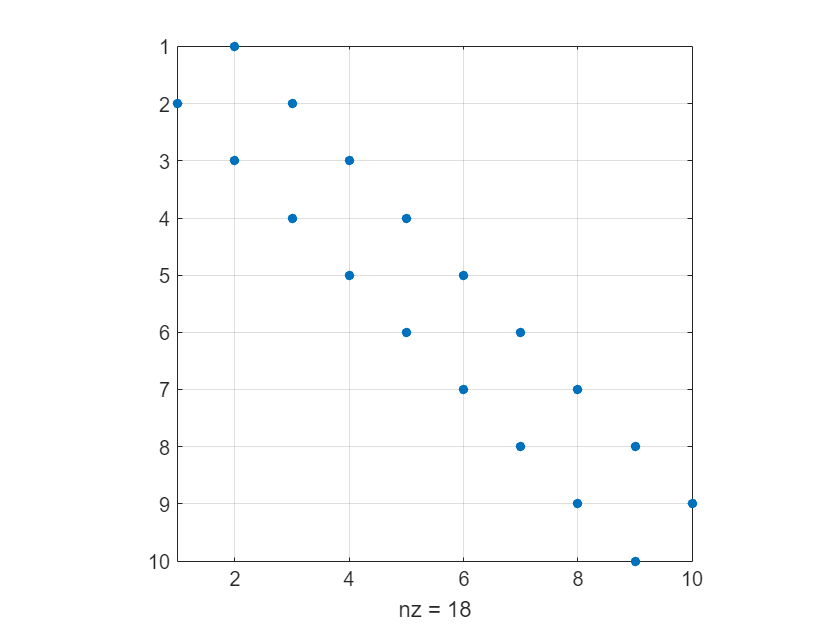

spy(A), grid on, axis equal, xlim([1 10]), ylim([1 10])

Reservar memoria para matriz dispersa

help spalloc

 spalloc Allocate space for sparse matrix.
    S = spalloc(M,N,NZMAX) creates an M-by-N all zero sparse matrix
    with room to eventually hold NZMAX nonzeros.
 
    For example
        s = spalloc(n,n,3*n);
        for j = 1:n
            s(:,j) = (a sparse column vector with 3 nonzero entries);
        end
 
    See also spones, spdiags, sprandn, sprandsym, speye, sparse.

    Documentation for spalloc
    Other uses of spalloc



Todas las operaciones funcionan con matrices dispersas. Salvo `cond`, que debe reemplazarse por` condest.`

#### **Ejercicio de c**onstrucción de una matriz por bloques

Construye una matriz **tridiagonal** $T\in \mathbb{R}^{4 \times 4}$con valores 2 en la diagonal principal y -1 en la diagonal superior e inferior.


$$T = \pmatrix{2 & -1 & 0 & 0 \cr -1 & 2 & -1 & 0 \cr 0 & -1 & 2 & -1 \cr 0 & 0 & -1 & 2 }.$$


Crea las siguientes matrices para completar los bloques:

- $A\in \mathbb{R}^{4 \times 4}$ es una matriz de unos.

- $B\in \mathbb{R}^{4 \times 4}$ es una matriz diagonal con los valores $(1,2,3,4)$ en la diagonal.

- $C\in \mathbb{R}^{4 \times 4}$ es una matriz de ceros.

Utiliza las matrices anteriores para construir una matriz por bloques $M\in\mathbb{R}^{8\times 8}$de la siguiente forma: 


$$M=\pmatrix{T & A \cr B & C}.$$


Multiplica la matriz $M$ por un escalar $k=3$ y calcula la nueva matriz $M_k = kM$.

Realiza el producto matricial $M_k\,M$y verifica si es inversible.

Define un vector $v\in\mathbb{R}^8$ tal que $v=(1, 2, 3, 4, 5, 6, 7, 8)^\top
$ 

Resuelve el sistema lineal $M_kM\,x =v$ y calcula el residuo.

run("../t1_soluciones/solucion1.m")

T =      2    -1     0     0
    -1     2    -1     0
     0    -1     2    -1
     0     0    -1     2


M =      2    -1     0     0     1     1     1     1
    -1     2    -1     0     1     1     1     1
     0    -1     2    -1     1     1     1     1
     0     0    -1     2     1     1     1     1
     1     0     0     0     0     0     0     0
     0     2     0     0     0     0     0     0
     0     0     3     0     0     0     0     0
     0     0     0     4     0     0     0     0


M_k*M:


MkM =     18    -6    12    12     3     3     3     3
    -9    24    -3    15     0     0     0     0
     6    -6    27     0     0     0     0     0
     3     9    -3    27     3     3     3     3
     6    -3     0     0     3     3     3     3
    -6    12    -6     0     6     6     6     6
     0    -9    18    -9     9     9     9     9
     0     0   -12    24    12    12    12    12


rank(M_k*M):


ans = 5

v =      1
     2
     3
     4
     5
     6
     7
     8


x =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   Inf


Norma del residuo:


ans = NaN

- **Celdas**

C = cell(1,3);
C{1} = 'text';
C{3} = [11; 22; 33]

C = 1×3 cell array
    {'text'}    {0×0 double}    {3×1 double}


`C =`

`  1×3 cell array`

`    {'text'}    {0×0 double}    {3×1 double}`

#### Estructuras

F = struct('u', @(x) exp(x)-cos(x), ...
           'v', @(x) x, ...
           'w', @(x) x^2)

F = struct with fields:
    u: @(x)exp(x)-cos(x)
    v: @(x)x
    w: @(x)x^2


F.u(2)

ans = 7.8052

% uso habitual agrupar datos asociados, clarifica la llamada a funciones:
% solve(F) vs solve(u,v,w) 

#### Algoritmia

- **Decisiones**

f = @(x) sin(x) % imaginemos que la evaluación de la función es costosa

f = function_handle with value:
    @(x)sin(x)


if 0
    disp('No entra')
elseif 2>1 || f(0) % or cortocircuito, no evalua f(0)
    disp('Entra')
else
    disp('No entra')
end

Entra


Observese que `|` (or) y `&` (and) representan el cálculo elemento a elemento

[1 0; 0 1] | [0 1; 1 0] 

ans = 2×2 logical array
   1   1
   1   1


Tambien existe [`switch`](https://es.mathworks.com/help/matlab/ref/switch.html) cuando los `elseif` se pueden clasificar en casos.

- **Bucles**

for i = 1:3
    disp(i)
end

     1

     2

     3



v = [2, 7, 99];
for i = 1:length(v)
    disp([i, v(i)])
end

     1     2

     2     7

     3    99



for vi = v
    disp(vi)
end

     2

     7

    99



Optimización, mejor inicializar la variable.

w = zeros(size(v));
for i = 1:length(v)
    w(i) = 1/v(i);
end
w

w =     0.5000    0.1429    0.0101


Mejor aún, ¡operaciones vectoriales!

w = 1./v

w =     0.5000    0.1429    0.0101


También existe [`while`](https://es.mathworks.com/help/matlab/ref/while.html), cuando la condición de terminación no es sencilla de expresar con un índice final.

[`continue`](https://es.mathworks.com/help/matlab/ref/continue.html) pasa el control a la siguiente iteración de un bucle. 

[`break`](https://es.mathworks.com/help/matlab/ref/break.html) termina la ejecución de un bucle. 

Buscar valores, [`find`](https://es.mathworks.com/help/matlab/ref/find.html).

A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


A > 5

ans = 3×3 logical array
   0   0   0
   0   0   1
   1   1   1


[i,j] = find(A>5)

i =      3
     3
     2
     3


j =      1
     2
     3
     3


Máximo de una matriz.

max(A) %máximo de cada columna

ans =      7     8     9


M = max(A,[],"all") %máximo de todos los elementos

M = 9

[M, I] = max(A,[],"all")

M = 9

I = 9

[row,col] = ind2sub(size(A),I)

row = 3

col = 3

### Estructuración de código

#### *Script*

Un *script* es un archivo que no define un *workspace* propio, usa el de Matlab.

¡Ojo! La carpeta de trabajo debe de ser la del *script.* Por ejemplo, pulsando botón derecho sobre el nombre del archivo en el editor y escogiendo *Change current folder to ...* 

type programa.m

a = 1;
b = 2; 
a+b;  % se guarda en ans


clear
a = 0 % esta variable cambiará tras ejecutar el script

a = 0

programa
a

a = 1

whos

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              
  ans       1x1                 8  double              
  b         1x1                 8  double              



#### Función anónima

- Se define en una línea (sustituye al `inline` de versiones anteriores*).*

x = 1;
g = @(t) x + t % x se toma del workspace

g = function_handle with value:
    @(t)x+t


g(2)

ans = 3

x = 2; g(2) % aunque x ha cambiado, g no cambia

ans = 3

g = @(t) x + t; % ahora g cambia
g(2)

ans = 4

#### Función .m

- Una función por archivo .m, debe haber coincidencia de nombres.

- *Workspace* propio.

- Argumentos de entrada (paso por valor).

- [`return`](https://es.mathworks.com/help/matlab/ref/return.html) sale de la función, pero es necesario para devolver valores.

type f1.m

function y = f1(x, y)
  % Ayuda de la función f1
  y = y + 2*x + 1;
  x = 1;
end


help f1

  Ayuda de la función f1



x = 0; y = 0;
f1(x,y)

ans = 1

x, y

x = 0

y = 0

Si se quiere retornar un cambio interno, debe asignarse:

y = f1(x,y);
x, y

x = 0

y = 1

Anonimizar una función con @ sirve para pasar funciones .m como argumento a otra función

type f2.m

function y = f2(f)
  y = f(0,0) + f(1,1);
end


h = @(x, y) sin(x+y)

h = function_handle with value:
    @(x,y)sin(x+y)


f2(h) %correcto

ans = 0.9093

f2(@f1) %correcto

ans = 5

#### Función local

- Aparece tras la primera función en un archivo.

- Sólo es accesible desde la primera función del archivo.

- Ejemplo, algoritmo de iteración funcional:

type f3.m

function y = f3(x)
y = g(x^2);
end
function y = g(x)
y = x+2;
end


f3(2)

ans = 6

#### Función anidada

- A mayores de las locales, además acceden a todas las variables de la contenedora sin necesidad de argumentos

type f4.m

function y = f4(x)
a = 3;
y = g(x^2);

function y = g(x)
y = x + a + 2;
end

end


f4(2)

ans = 9

- **Ejemplo práctico: **resolver la EDO no lineal $y'' = F(x,y,y') = u(x) + v(x)y^m+w(x)y'$

En la iteración $k$ del algoritmo de iteración funcional hay que resolver la EDO lineal $y'' = u(x) + \tilde{v}(x)y+w(x)y'$ donde $\tilde{v}(x) = v(x)y_k^{m-1}$

`function y = df(v)`

`  %resuelve el caso lineal, para una v(x) dada`

`end`

`function y = dfif(v)`

`  for k = 1:maxit`

`    yk = df(@v_tilde)`

`  end`

`  function y = v_tilde(x)`

`  y = v(x) * yk^(m-1)`

`  % v_tilde debe depender solo de x para adecuarse al caso lineal`

`  % Debe concer yk sin ser su argumento`

`  end`

`end`

A veces, es posible usar otras herramientas, por ejemplo, funciones anónimas:

`function y = dfif(v)`

`  for k = 1:maxit`

`    v_tilde = @(x) v(x) * yk^(m-1)`

`    yk = df(@v_tilde)`

`  end`

`end`

#### Funciones en carpeta private

- Sólo accesibles desde archivos de la carpeta contenedora, i.e., como si fuesen locales a todos ellos.

type prv.m

function y = prv(x)
y = x^2;
end


type f5.m

function y = f5(x)
y = prv(x) + 1;
end


f5(2)

ans = 5

Ejemplo de uso, funciones con magnitudes físicas necesarias para varios algoritmos de resolución de una EDP.

#### Funciónes o *scripts* en otras carpetas

- Añadir carpeta al [`path`](https://es.mathworks.com/help/matlab/ref/path.html) o ejecutar con `run(ruta)`.

- En esta materia las funciones se comunicarán sólo a través de argumentos (no usaremos `global`).

#### Número variable de argumentos de entrada

`varargin` es una celda con los argumentos adicionales

 type f6.m

function y = f6(x, varargin)
switch nargin
    case 1
        y = x;
    case 2
        y = x + varargin{1}(x);
    case 3
        y = x + varargin{1}(x) + varargin{2}(x);
    otherwise
        error('Solo se permiten a lo sumo dos argumentos opcionales.')
end
end


 f6(1)

ans = 1

 f6(1, @(x) exp(x))

ans = 3.7183

Ejemplo, modificadores de ciertos algoritmos (bloqueo en elementos finitos)

#### Número variable de argumentos de salida

El comportamiento de una función puede cambiar dependiendo del número de salidas que se soliciten. Véase, por ejemplo, `max`. 

`varargout` es una celda con los argumentos de salida adicionales. Para usarlo en nuestro código  es bueno saber el número de argumentos de salida, `nargout`.

El siguiente ejemplo usa la función `sins`, local a este *script*.

[s1,s2] = sins()

s1 = function_handle with value:
    @(x)sin(k*x)


s2 = function_handle with value:
    @(x)sin(k*x)


s1(1), s2(1)

ans = 0.8415

ans = 0.9093

sin(1), sin(2)

ans = 0.8415

ans = 0.9093

#### Funciones sobre vectores

Las funciones matemáticas "deberían" admitir vectores (i.e., usar operaciones elementales).

g = @(x) x.^2;
t = 1:10;
plot(t, g(t))

Las funciones con condiciones if no admitirán vectores directamente:

x = [-1 2];
x > 0

ans = 1×2 logical array
   0   1


if x >= 0
    y = 1
else
    y = -1
end

y = -1

Se puede aplicar cualquier función a cada elemento de un vetor o matriz con [`arrayfun`](https://es.mathworks.com/help/matlab/ref/arrayfun.html).

arrayfun(@fl, x)

ans =     -1     1


#### Depuración

- Primero, comprobar los avisos (naranja) y errores (rojo).

- Puntos de interrupción. Por ejemplo, dentro de `sins()`

- *Step, step in, step out, continue* y *stop.*

- En la ventana de comandos, imprimir variables.

#### Ejercicio de funciones anidadas

Se desea implementar el **método de punto fijo** para resolver la ecuación $x=f(x)$ , donde la función $f(x)$ varía dependiendo de un parámetro $a$. El objetivo es implementar paso a paso las funciones necesarias y luego hacer una prueba para varios valores del parámetro $a$.

La función $f(x)$ estará definida como $f(x)=a\cdot \cos (x)$.

Implementa la función `pfijo(f, x0)`, que realiza el método de punto fijo cuando recibe una función `f`, un valor inicial `x0`, y devuelve el valor del iterante final $x$, el número de iteraciones realizadas $k$ y un indicador de convergencia $conv$.

Debe calcula reiteradamente $x_{n+1} = f(x_n)$ y usar una condición de parada basada en la diferencia absoluta entre iterantes consecutivos menor que $1e-13$ o hasta un máximo de 100 iteraciones.

El programa debe probar el método de punto fijo para $x_0=0,5$ y diferentes valores de $a$, de $0$ a $2$ con paso $0,2$. Imprime los resultados de $a$, $x$, $k$ y si el método ha convergido para cada valor de $a$.

**Observación:** El punto fijo será un atractor si la derivada de la función $f$ en el punto fijo cumple $|f\prime (x)|<1$. Por tanto, la convergencia depende de $a$. Para valores pequeños convergerá rápidamente. Para valores de $a>1$, es probable que el método no converja, ya que la pendiente de la función se vuelve mayor y el método pierde estabilidad.

run("../t1_soluciones/solucion2.m")

a, x, k, conv
     0     0     2     1

    0.2000    0.1962   11.0000    1.0000

    0.4000    0.3726   16.0000    1.0000

    0.6000    0.5205   23.0000    1.0000

    0.8000    0.6411   40.0000    1.0000

    1.0000    0.7391   75.0000    1.0000

    1.2000    0.8193  100.0000         0

    1.4000    0.3619  100.0000         0

    1.6000   -0.0442  100.0000         0

    1.8000   -0.2832  100.0000         0

    2.0000   -0.7540  100.0000         0



## **Anexo. Funciones locales**

En Matlab, las funciones locales utilizadas en un *script*, van al final de éste.

function [varargout] = sins()
varargout = cell(1, nargout);
for k = 1:nargout
    varargout{k} = @(x) sin(k*x);
end
end

function y = fl(x)
if x >= 0
    y = 1;
else
    y = -1;
end
end